# MulGETS application example

## 1. Generate stochastic data of daily precipitation

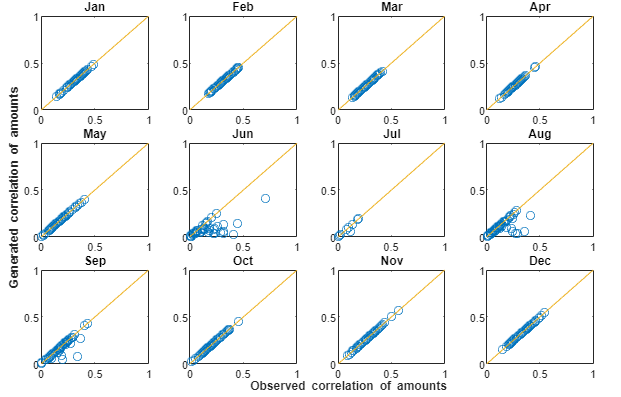

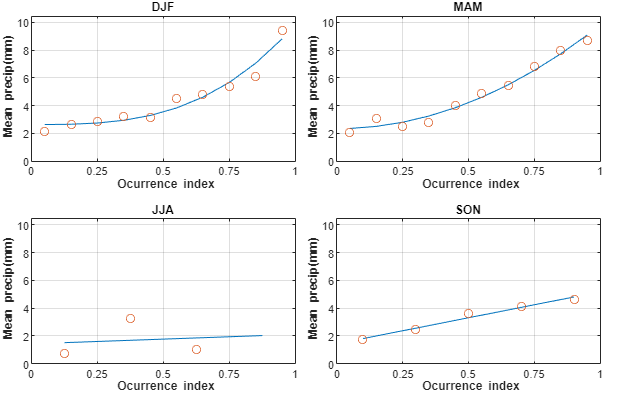

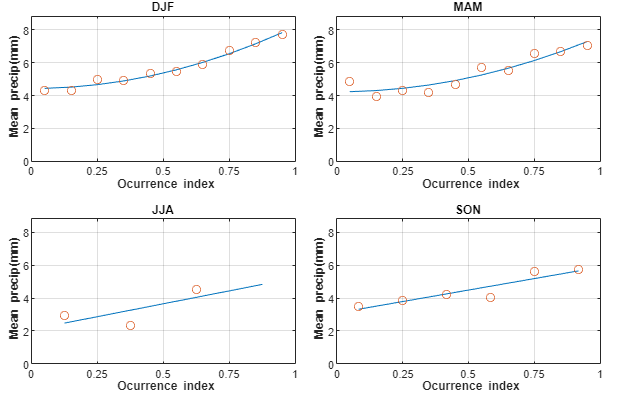

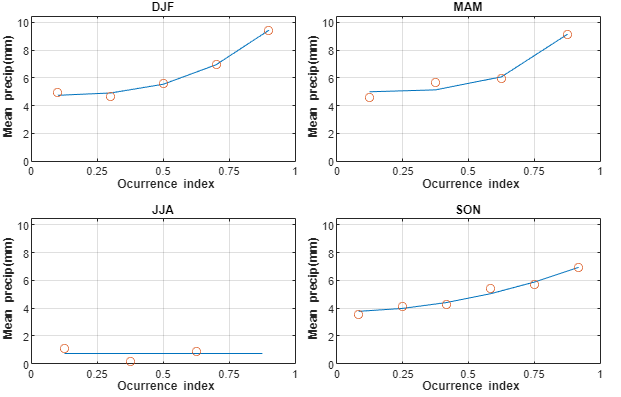

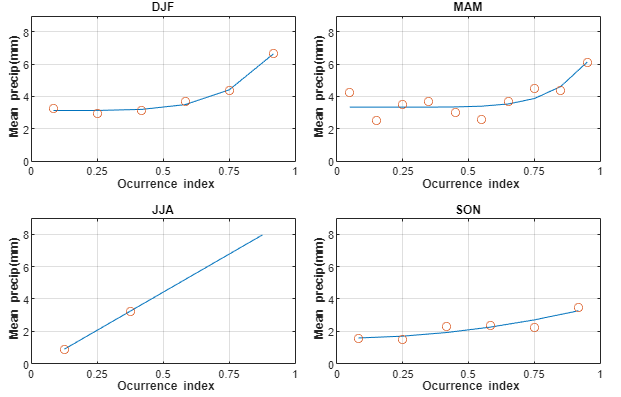

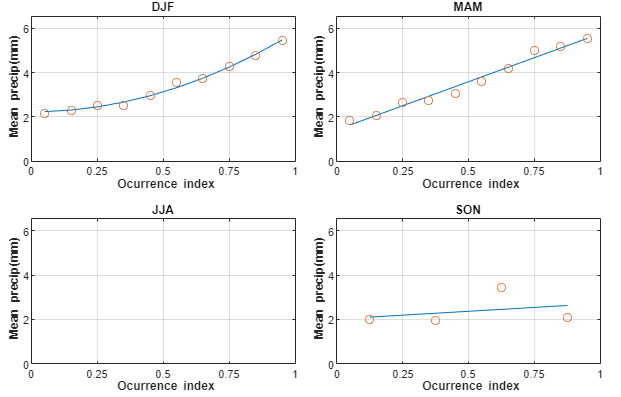

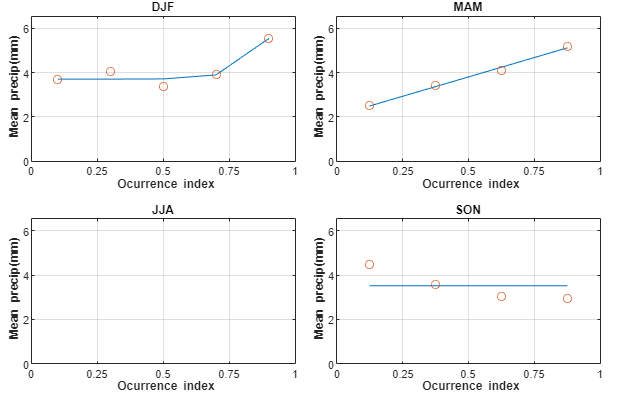

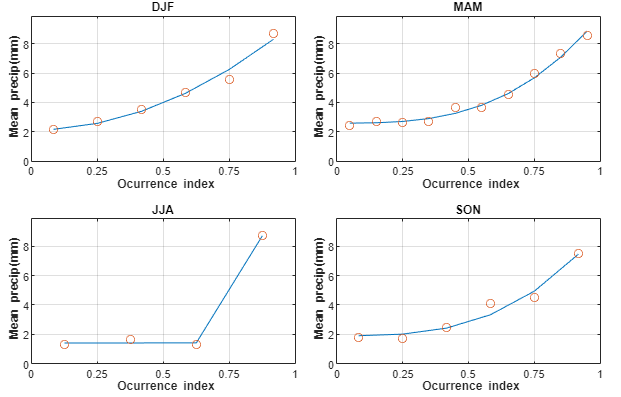

clear
clc
TTpr_obs = readtimetable('precip.xlsx');
dist = 1; % multiexp 1, multigamma 2.
nYears = 1000;
pivotYear = 1964;
graph = 1;
warning('off')
tic,
TTpr_gen = mulgets(TTpr_obs, dist, nYears, pivotYear, graph);

toc

Elapsed time is 49.470401 seconds.


## 2. Monthly statistical comparison

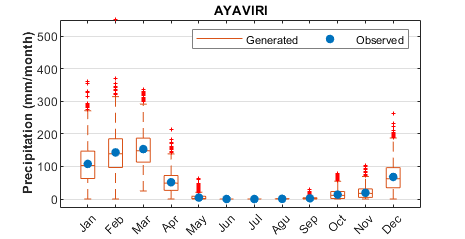

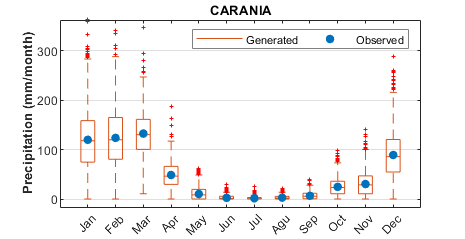

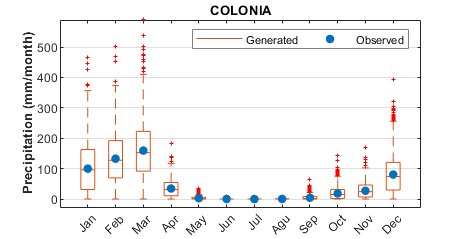

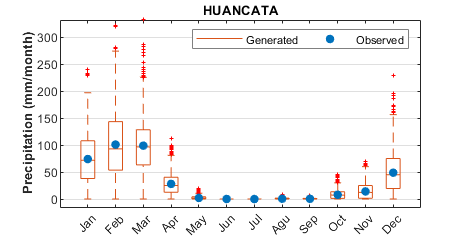

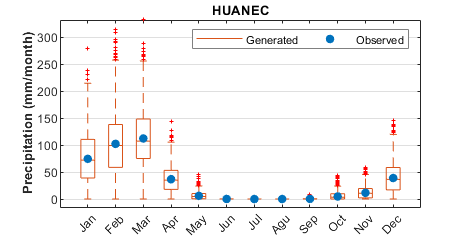

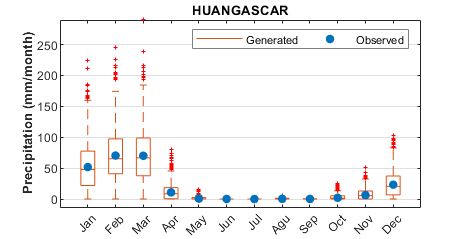

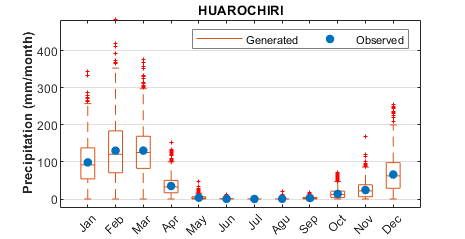

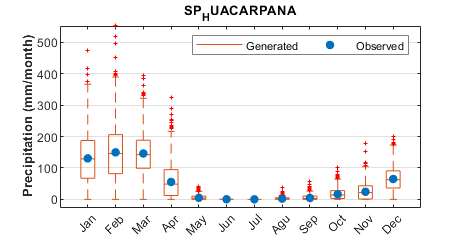

% Accumulation
TTpr_obs_mon = retime(TTpr_obs, 'monthly', 'sum');
TTpr_gen_mon = retime(TTpr_gen, 'monthly', 'sum');

% Mean and std observed
TTpr_obs_mon.Month = TTpr_obs_mon.Properties.RowTimes.Month;
StatsObs = [];
StatsObs.mean = varfun(@mean, TTpr_obs_mon, 'GroupingVariables', 'Month',  'OutputFormat', 'uniform');
StatsObs.std = varfun(@std, TTpr_obs_mon, 'GroupingVariables', 'Month',  'OutputFormat', 'uniform');
StatsObs.std(StatsObs.std == 0) = 0.01; % tolerance
TTpr_obs_mon = removevars(TTpr_obs_mon, 'Month');

% Mean and std generated
TTpr_gen_mon.Month = TTpr_gen_mon.Properties.RowTimes.Month;
StatsGen = [];
StatsGen.mean = varfun(@mean, TTpr_gen_mon, 'GroupingVariables', 'Month',  'OutputFormat', 'uniform');
StatsGen.std = varfun(@std, TTpr_gen_mon, 'GroupingVariables', 'Month',  'OutputFormat', 'uniform');
StatsGen.std(StatsGen.std == 0) = 0.01;
TTpr_gen_mon = removevars(TTpr_gen_mon, 'Month');

% Correct bias of generated time series
obsMean = repmat(StatsObs.mean, nYears, 1);
obsStd = repmat(StatsObs.std, nYears, 1);
genMean = repmat(StatsGen.mean, nYears, 1);
genStd = repmat(StatsGen.std, nYears, 1);
m = ((TTpr_gen_mon.Variables - genMean)./genStd).*obsStd + obsMean; % Correction eq.
m(m < 0) = 0;
TTpr_gencorr_mon = array2timetable(m, 'RowTimes', TTpr_gen_mon.Properties.RowTimes, 'VariableNames', TTpr_gen_mon.Properties.VariableNames);

% Plot
nStns = width(TTpr_obs);
for j = 1:nStns   
    figure
    set(gcf, 'Position', [476.6364 535.9818 405.8182 209.4545])
    set(gcf, 'Color', 'w')
    axes('XTick', 1:12,...
        'XLim', [0, 13],...
        'YLim', [0, Inf],...
        'FontSize', 8,...
        'YGrid', 'on');
    hold on
    plot(0, 0, 'Color', [0.8500 0.3250 0.0980])
    m = reshape(TTpr_gencorr_mon{:,j}, 12, []).';
    boxplot(m,'OutlierSize', 2, 'Colors', [0.8500 0.3250 0.0980], ...
        'label', {'Jan','Feb','Mar','Apr', 'May', 'Jun', 'Jul', 'Agu', 'Sep', 'Oct', 'Nov', 'Dec'})
    plot(1:12, StatsObs.mean(:,j), 'o', 'MarkerSize', 5, 'MarkerFaceColor', [0 0.4470 0.7410],...
        'MarkerEdgeColor', [0 0.4470 0.7410])
    title(TTpr_obs.Properties.VariableNames{j})
    ylabel('\bf Precipitation (mm/month)')
    legend({'Generated', 'Observed'}, 'Orientation', 'horizontal', 'EdgeColor', [0.5, 0.5, 0.5])
    hold off
end

## 3. Annual statistical comparison

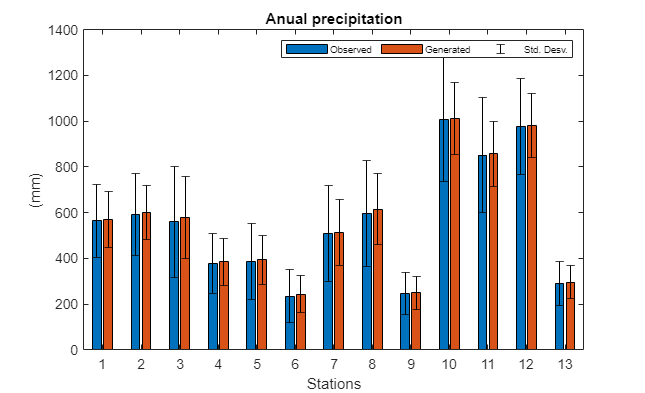

% Accumulation
TTpr_obs_annual = retime(TTpr_obs_mon, 'yearly', 'sum');
TTpr_gen_annual = retime(TTpr_gencorr_mon, 'yearly', 'sum');

% Statistics
func = @(x) [mean(x); std(x)];
TstatsObs = varfun(func, TTpr_obs_annual, 'OutputFormat','table');
TstatsGen = varfun(func, TTpr_gen_annual, 'OutputFormat','table');

% Plot
figure('Position', [476.6364 364.9273 624.8727 380.5091])
b = bar([TstatsObs{1,:}.', TstatsGen{1,:}.']);
hold on
e = errorbar([b(1).XEndPoints, b(2).XEndPoints], [b(1).YEndPoints, b(2).YEndPoints], [TstatsObs{2,:}, TstatsGen{2,:}], 'k|');
title('Anual precipitation')
ylabel('(mm)')
xlabel('Stations')
legend([b, e], {'Observed', 'Generated', 'Std. Desv.'}, 'FontSize', 7, 'Orientation', 'horizontal')
hold off